# ROBOTICS LAB - 2

## BL.EN.U4CSE23239


q = UnitQuaternion(rpy2tr(0.1,0.2,0.3))

 
q = 
 
0.98335 < 0.034271, 0.10602, 0.14357 >
 


q1 = inv(q)

 
q1 = 
 
0.98335 < -0.034271, -0.10602, -0.14357 >
 


q*q1

 
ans = 
 
1 < 0, 0, 0 >
 


q/q

 
ans = 
 
1 < 0, 0, 0 >
 


q.R()

ans =     0.9363   -0.2751    0.2184
    0.2896    0.9564   -0.0370
   -0.1987    0.0978    0.9752


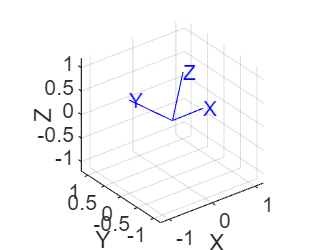

clf;
axis([-4 4 -4 4 -4 4]);     
view(3);
q.plot()


Rx = rotx(90,'deg')

Rx =      1     0     0
     0     0    -1
     0     1     0


q = UnitQuaternion(Rx)

 
q = 
 
0.70711 < 0.70711, 0, 0 >
 


q.plot('frame','A')
q1 = inv(q)

 
q1 = 
 
0.70711 < -0.70711, 0, 0 >
 


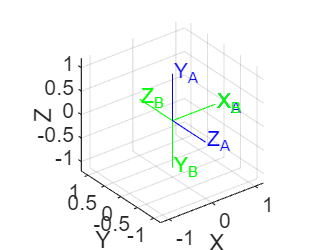

hold on
q1.plot('frame','B','color','g')

q.angle(q1)

ans = 1.5708

## 1)


A = UnitQuaternion(rotx(45,"deg")*roty(60,"deg"))

 
A = 
 
0.8001 < 0.33141, 0.46194, 0.19134 >
 


B = UnitQuaternion(roty(60,'deg')*rotx(60,"deg"))

 
B = 
 
0.75 < 0.43301, 0.43301, -0.25 >
 


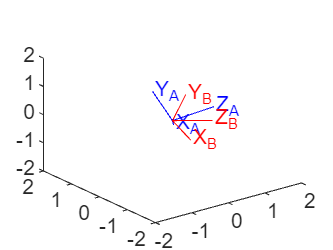

clf;
axis([-2 2 -2 2 -2 2]);     
view(3);
hold on
A.plot('frame','A')

B.plot('frame','B','color','r')

## 2)


A = UnitQuaternion(rotz(30,"deg")*rotx(80,"deg")*roty(126,"deg"))

 
A = 
 
0.18769 < 0.10522, 0.73482, 0.64322 >
 


B = UnitQuaternion(roty(126,'deg')*rotx(80,"deg")*rotz(30,"deg"))

 
B = 
 
0.48416 < 0.45853, 0.58376, -0.4632 >
 


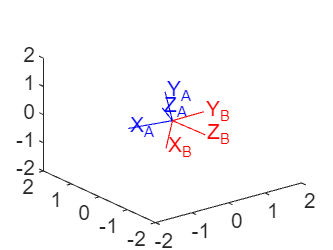


clf;
axis([-2 2 -2 2 -2 2]);     
view(3);
hold on
A.plot('frame','A')

B.plot('frame','B','color','r')